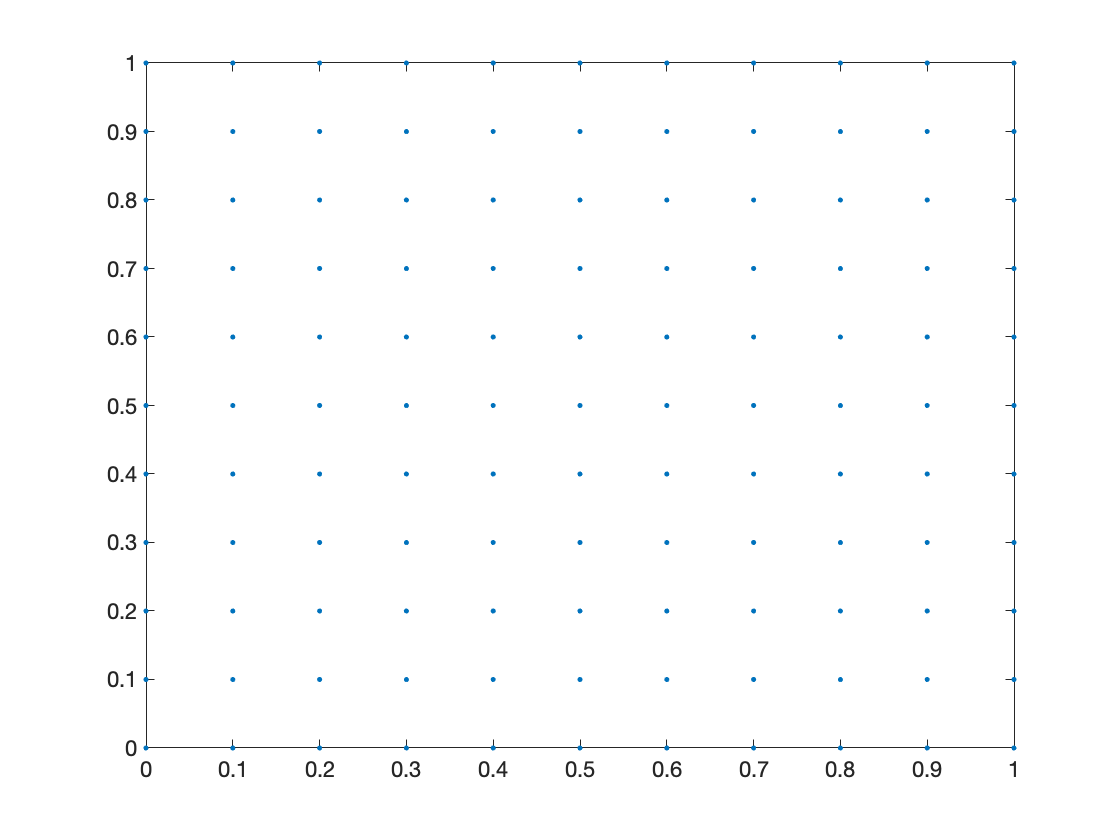

h = 1/10;
x=0:h:1; M=length(x);

% 2-lines
col = repmat(x, 1, M);
row = reshape(repmat(x, M, 1),[numel(repmat(x, M, 1)), 1]);
plot(row, col, ".")

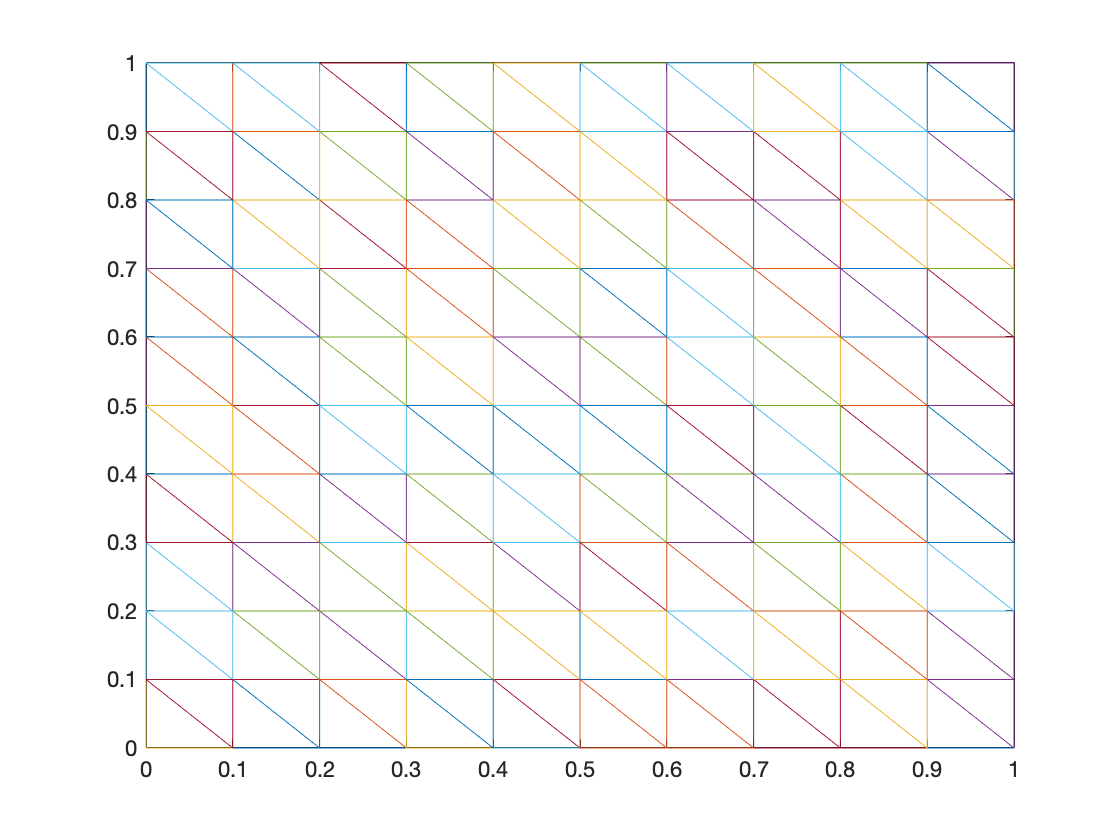

N = [row, col'];
T=delaunay(N);
trimesh(T, N(:,1),N(:,2))

nx = length(x);
T=[];
for m = 1:nx-1
    for k =1:nx-1
        T = [T; nx*(m-1)+k nx*(m-1)*k+1 nx*m+k+1];
        T = [T; nx*(m-1)+k nx*m+k+1 nx*m+k];
    end
end